clear

root_dir = 'E:\Dropbox\SEL\BOX\OpenSim\_Main_\c_AddBio_Continous'

root_dir = 'E:\Dropbox\SEL\BOX\OpenSim\_Main_\c_AddBio_Continous'

sub_name = 'SUB1';
APP = 'APP2';
kg_bpm = ['15_10'; '15_16'];
UpDown = ['U'; 'D'];


for trial_num = 1:2
    for kb = 1:2-1
        for ud = 1:2
            for task_num = 1:10
                file_name = [sub_name ,'_', kg_bpm(kb,:) ,'_', num2str(trial_num) ,'_', UpDown(ud,:) , num2str(task_num) ,'_', APP ,'_BodyKinematics_pos_global.sto'];
                file_path = [root_dir ,'\\', sub_name ,'\\', APP ,'\\', 'trial', kg_bpm(kb,:) ,'_', num2str(trial_num) ,'\\BK_Results','\\', file_name];
                
                pos = ImportHandRL_pos(file_path);
                ggpos.Rx = gradient(gradient(pos(:,1)))*10000;
                ggpos.Ry = gradient(gradient(pos(:,2)))*10000;
                ggpos.Rz = gradient(gradient(pos(:,3)))*10000;
                ggpos.Lx = gradient(gradient(pos(:,4)))*10000;
                ggpos.Ly = gradient(gradient(pos(:,5)))*10000;
                ggpos.Lz = gradient(gradient(pos(:,6)))*10000;
                
                save_name = [sub_name ,'_', kg_bpm(kb,:) ,'_', num2str(trial_num) ,'_', UpDown(ud,:) , num2str(task_num) ,'_', APP ,'_BodyKinematics_acc.csv'];
                save_path = [root_dir ,'\\', sub_name ,'\\', APP ,'\\', 'trial', kg_bpm(kb,:) ,'_', num2str(trial_num) ,'\\BK_Results','\\', save_name];
                writetable(struct2table(ggpos), save_path)
            end
        end
    end
end


clear

root_dir = 'E:\Dropbox\SEL\BOX\OpenSim\_Main_\c_AddBio_Continous'

root_dir = 'E:\Dropbox\SEL\BOX\OpenSim\_Main_\c_AddBio_Continous'

sub_name = 'SUB1';
APP = 'APP2_OneCycle';
kg_bpm = ['15_10'; '15_16'];



for trial_num = 1:2
    for kb = 1:2-1
        for task_num = 1:10
            file_name = [sub_name ,'_', kg_bpm(kb,:) ,'_', num2str(trial_num) ,'_12sec_', num2str(task_num) ,'_', APP ,'_BodyKinematics_pos_global.sto'];
            file_path = [root_dir ,'\\', sub_name ,'\\', APP ,'\\', 'trial', kg_bpm(kb,:) ,'_', num2str(trial_num) ,'\\BK_Results','\\', file_name];
            
            pos = ImportHandRL_pos(file_path);
            ggpos.Rx = gradient(gradient(pos(:,1)))*10000;
            ggpos.Ry = gradient(gradient(pos(:,2)))*10000;
            ggpos.Rz = gradient(gradient(pos(:,3)))*10000;
            ggpos.Lx = gradient(gradient(pos(:,4)))*10000;
            ggpos.Ly = gradient(gradient(pos(:,5)))*10000;
            ggpos.Lz = gradient(gradient(pos(:,6)))*10000;
            
            save_name = [sub_name ,'_', kg_bpm(kb,:) ,'_', num2str(trial_num) ,'_12sec_', num2str(task_num) ,'_', APP ,'_BodyKinematics_acc.csv'];
            save_path = [root_dir ,'\\', sub_name ,'\\', APP ,'\\', 'trial', kg_bpm(kb,:) ,'_', num2str(trial_num) ,'\\BK_Results','\\', save_name];
            writetable(struct2table(ggpos), save_path)
        end
    end
end


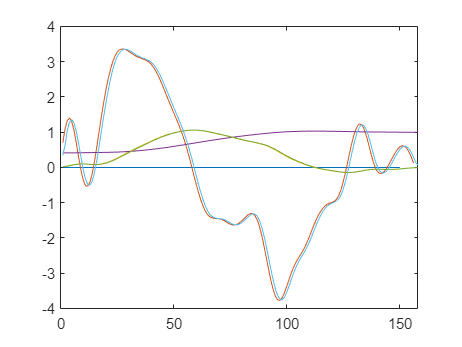

% % plot test
% hold off

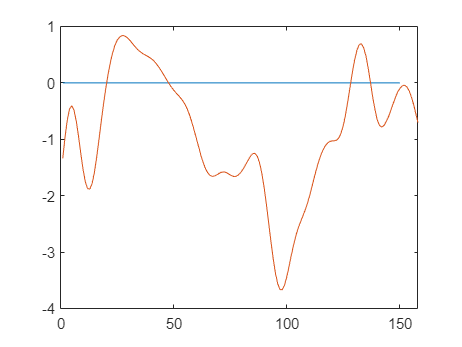

% y=zeros(150,1);
% plot(y)
% hold on
% 
% plot(acc(:,2));

% ddpos = diff(diff(pos))*10000;

ddpos =    -0.7193    0.6999   -0.2506
   -0.6852    1.0900   -0.1479
   -0.6148    1.3350   -0.0510
   -0.5065    1.4040    0.0349
   -0.3703    1.2956    0.1096
   -0.2278    1.0407    0.1683
   -0.1046    0.6882    0.2091
   -0.0202    0.2989    0.2317
    0.0219   -0.0647    0.2386
    0.0303   -0.3480    0.2377


% dpos = diff(pos)*100;

dpos =     0.0273    0.0222    0.0316
    0.0201    0.0292    0.0291
    0.0133    0.0401    0.0276
    0.0071    0.0534    0.0271
    0.0021    0.0675    0.0274
   -0.0016    0.0804    0.0285
   -0.0039    0.0908    0.0302
   -0.0049    0.0977    0.0323
   -0.0051    0.1007    0.0346
   -0.0049    0.1001    0.0370


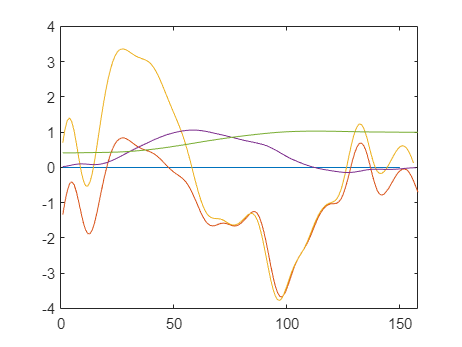

% plot(ddpos(:,2));
% plot(dpos(:,2));
% plot(pos(:,2));

% gpos = gradient(pos(:,2))*100;

gpos =     0.0222
    0.0257
    0.0346
    0.0468
    0.0605
    0.0740
    0.0856
    0.0943
    0.0992
    0.1004


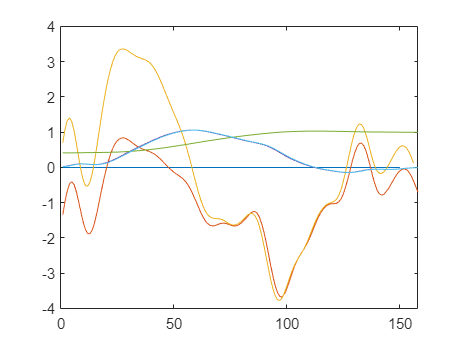

% plot(gpos)

% ggpos = gradient(gradient(pos(:,2)))*10000;

ggpos =     0.3499
    0.6224
    1.0537
    1.2910
    1.3597
    1.2590
    1.0163
    0.6790
    0.3053
   -0.0446


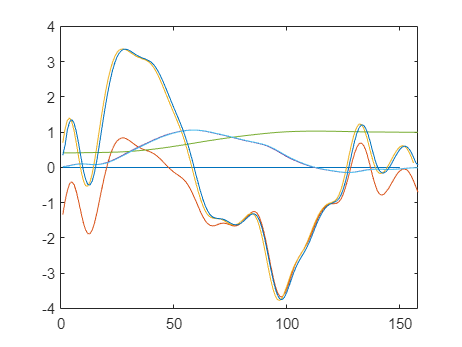

% plot(ggpos)